# Explore Data

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the table `data` which contains the basketball player data.

data = readtable("./data/bballData.csv")

data = 609×22 table
      playerID                name               pos      height    weight     GP     minutes    points    oRebounds    dRebounds    rebounds    assists    steals    blocks    turnovers     PF     fgAttempted    fgMade    ftAttempted    ftMade    threeAttempted    threeMade
    _____________    ______________________    _______    ______    ______    ____    _______    ______    _________    _________    ________   

## Task 1

You can plot some results from the basketball player data to explore relationships between various statistics and player position.

For example, the `boxplot` function can create a box plot of the points scored for each position:

`boxplot``(``data.points``,``data.pos``)`

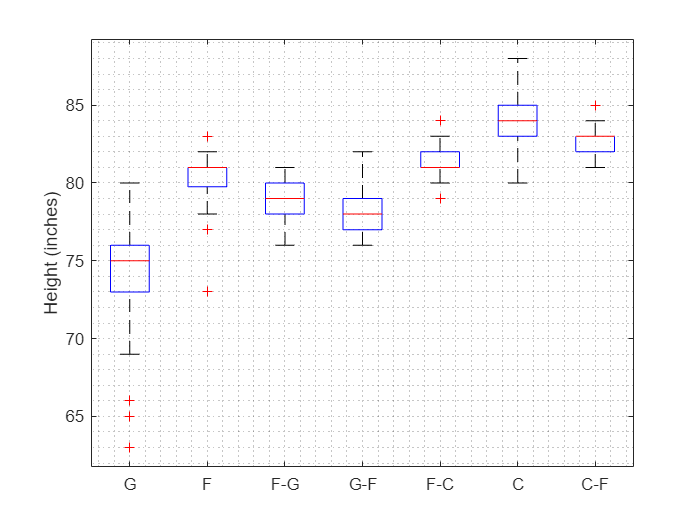

boxplot(data.height, data.pos)
grid minor
ylabel("Height (inches)")

## Task 2

It looks as though guards (G) are generally shorter than forwards (F) or centers (C). What other patterns can we find in the data?

You can use `gscatter` to explore the relationship between two variables, grouped by position.

`gscatter``(``data.``varX``,``data.``varY``,``data.pos``)`

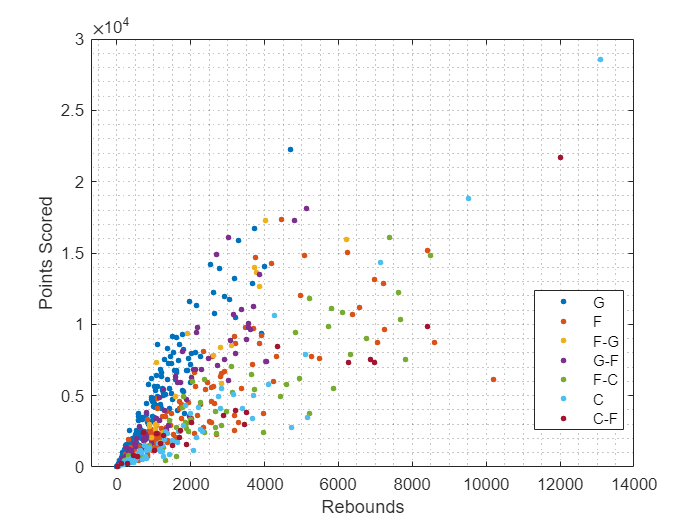

gscatter(data.rebounds, data.points, data.pos)
grid minor
xlabel("Rebounds")
ylabel("Points Scored")

## Task 3

You can see some groupings for different positions. However, the data's range makes it difficult to compare players, since most players are clustered tightly around the origin.

Some players played much more than others, leading to higher total points and rebounds. One way to account for this difference is to divide points and rebounds by the number of games played.

In the table `data`, the variable `GP` contains the number of games played. You can use element-wise division (`./`) to calculate per game statistics.

`data.``variable``./``data.GP`

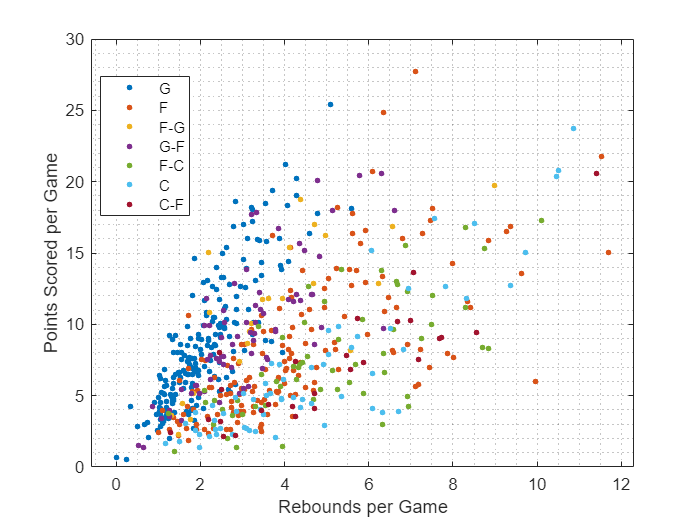

gscatter(data.rebounds./data.GP, data.points./data.GP, data.pos)
grid minor
xlabel("Rebounds per Game")
ylabel("Points Scored per Game")

## Task 4

The data points are no longer clustered around the origin, but the data points for each position are still spread out. Can a different normalization yield more insight?

Another way to account for difference in play time is to divide by the number of minutes played, `data.minutes`.

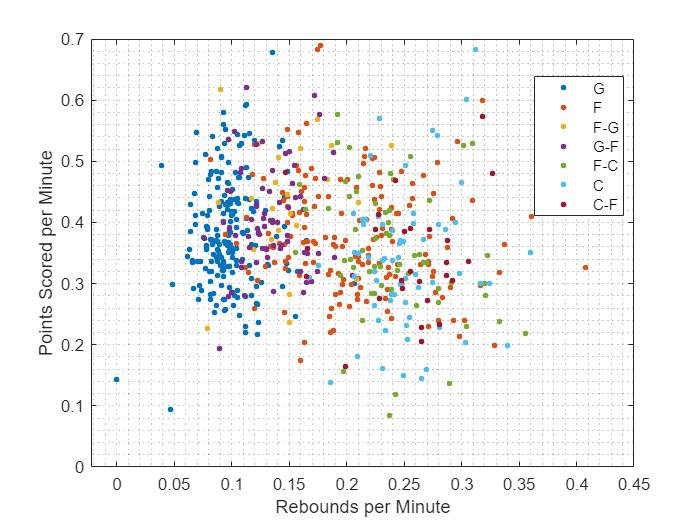

gscatter(data.rebounds./data.minutes, data.points./data.minutes, data.pos)
grid minor
xlabel("Rebounds per Minute")
ylabel("Points Scored per Minute")